# TC Study

For a convincing traction control, it needs to be studied how optimum slip ratio is changed based on Fz, but also SA, as any lateral force could change the longitudinal slip characteristics of a tire. This study will investigate this phenomenon for multiple Hoosier tires given TTC data. The test data is available at fsaettc.org

List of all 13" rim tires:

20.5x7 R20 - Round 9, Run 20, Run 54

20.5x7 R25B - Round 6, Run 12, Run 58

## R25B

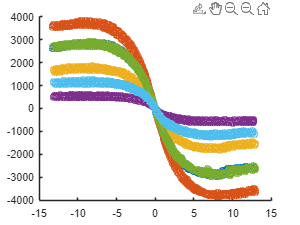

load("B1654run12.mat");
FzSweep = [222,445,660,889,1112];

% 0-7671 IA = 0
run12 = [
	% start, end , Fz
	1,1264,1112;
	1265,2550,1557;
	2551,3835,660;
	3836,5103,222;
	5127,6382,1112;
	6390,7671,445;
];

figure
hold on
for i = 1:size(run12,1)
	startIndex = run12(i,1);
	endIndex = run12(i,2);
	
	scatter(SA(startIndex:endIndex), FY(startIndex:endIndex));
end

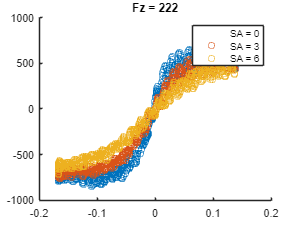

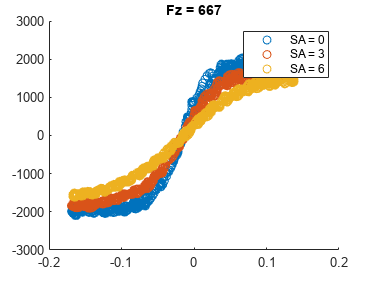

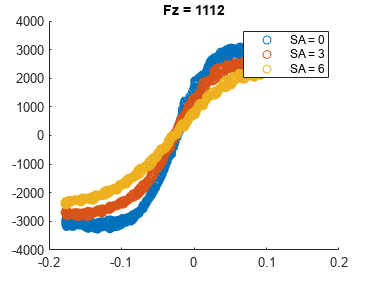

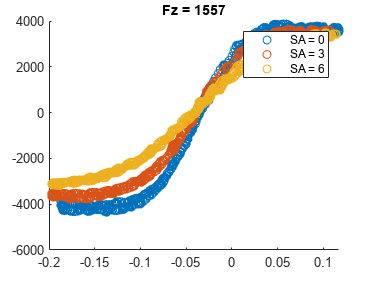


load("B1654run55.mat");

run55 = [
    % start, end, Fz, SA
    % 1-9218: SA = 0
    % 9401-17402: SA = -3
    % 17583-25645: SA = -6

    % IA = 0 section, SA = 0
       1,  1287, 1112,  0;
    1288,  1952, 1557,  0;
    1953,  2629,  667,  0;
    2630,  3305, 1112,  0;
    3306,  3998,  222,  0;

    % IA = 0 section, SA = -3
    9401,  9897, 1557, -3;
    9898, 10598,  667, -3;
   10599, 11326, 1112, -3;
   11327, 12042,  222, -3;

    % IA = 0 section, SA = -6
   17583, 18186, 1557, -6;
   18187, 18889,  667, -6;
   18890, 19615, 1112, -6;
   19616, 20280,  222, -6;
];


for fz = [222,667,1112,1557]
	figure
	hold on
	for slipAngle = [0,-3,-6]
		indexRow = find(run55(:,4)==slipAngle & run55(:,3)==fz);
		indexRow = indexRow(1);
		startIndex = run55(indexRow(1),1);
		endIndex = run55(indexRow(1),2);
		
		scatter(SR(startIndex:endIndex),FX(startIndex:endIndex));
	end
	legend(["SA = 0","SA = 3","SA = 6"]);
	title("Fz = " + num2str(fz))
end

It's noted that longitudinal slip peak shifts out as SA increases, but the SR range of TTC testing rig is too small to capture the peaks.

Need to fit a simplified tire model to extrapolate